# Modelado Dinámico de un Eslabón

## Resumen (Abstract y Summary)

Que es lo que presenta el documento.

## Definición de funciones

%Symbolic funtion definition
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Homogeneous transform
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelo cinemático del eslabón

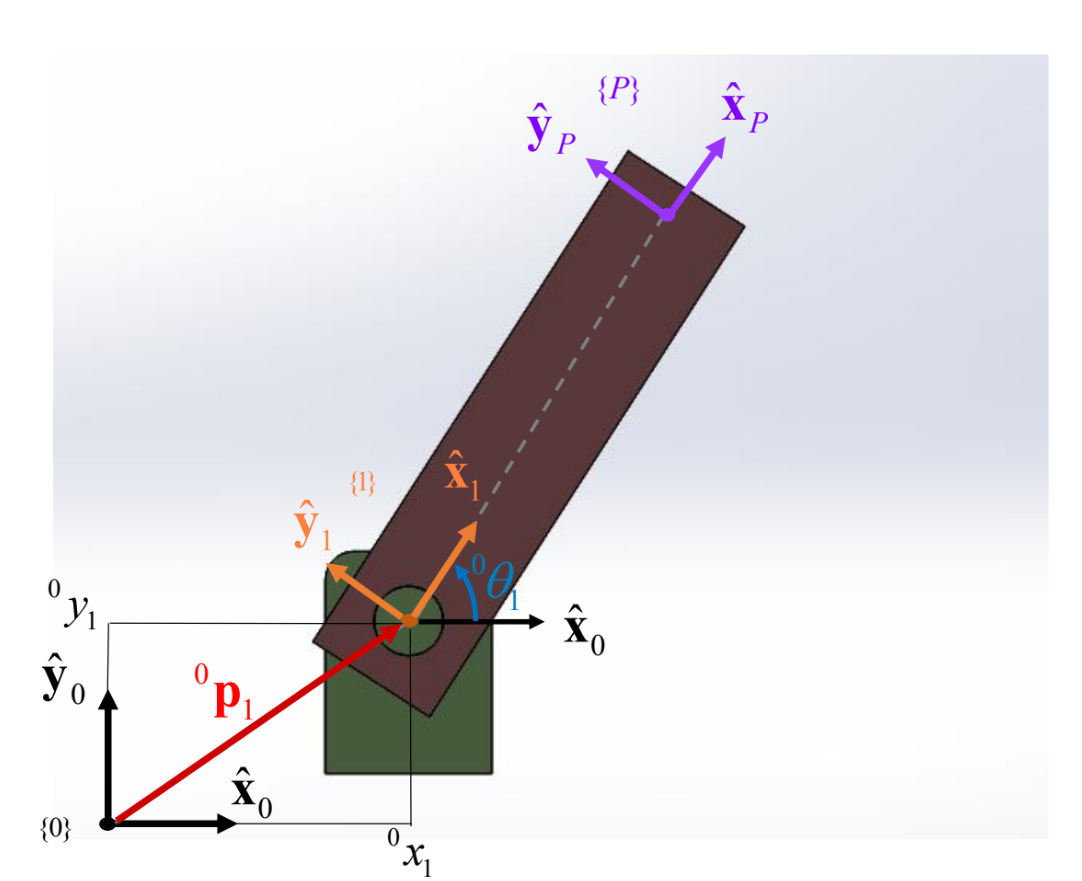

% Definicion de las tranformaciones homogeneas
syms x_O_1 y_O_1 theta_O_1 L_1

T_O_1 = Tij(x_O_1, y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_P = Tij(L_1, 0,0,0,0,0)

$$T\_1\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_P = T_O_1*T_1_P

$$T\_O\_P = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+L_{1}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Definición del vector de postura

xi_O_P_q = [T_O_P(1,4); T_O_P(2,4); theta_O_1 ]

$$xi\_O\_P\_q = \left(\begin{array}{c} x_{O,1}+L_{1}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \theta_{O,1} \end{array}\right)$$

syms x_O_P y_O_P theta_O_P

xi_O_P = [x_O_P; y_O_P; theta_O_P]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,P}\\ y_{O,P}\\ \theta_{O,P} \end{array}\right)$$

Modelo cinemático directo de las velocidades

Calculo del vector de velocidades

syms x_dot_O_P y_dot_O_P theta_dot_O_P theta_dot_O_1 % variables que definen la velocidad

xi_dot_O_P = diff(xi_O_P,x_O_P)*x_dot_O_P + diff(xi_O_P,y_O_P)*y_dot_O_P + diff(xi_O_P,theta_O_P)*theta_dot_O_P

$$xi\_dot\_O\_P = \left(\begin{array}{c} {\dot{x}}_{O,P}\\ {\dot{y}}_{O,P}\\ {\dot{\theta }}_{O,P} \end{array}\right)$$


xi_dot_O_P_q = diff(xi_O_P_q, theta_O_1)*theta_dot_O_1

$$xi\_dot\_O\_P\_q = \left(\begin{array}{c} -L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\\ L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

Modelo cinemático de las aceleraciones

syms theta_ddot_O_P theta_ddot_1_P

xi_ddot_O_P_q = diff(xi_dot_O_P_q, theta_O_1)*theta_dot_O_P + diff(xi_dot_O_P_q, theta_dot_O_1)*theta_ddot_1_P

$$xi\_ddot\_O\_P\_q = \left(\begin{array}{c} -L_{1}\,{\ddot{\theta }}_{1,P}\,\sin\left(\theta_{O,1}\right)-L_{1}\,{\dot{\theta }}_{O,1}\,{\dot{\theta }}_{O,P}\,\cos\left(\theta_{O,1}\right)\\ L_{1}\,{\ddot{\theta }}_{1,P}\,\cos\left(\theta_{O,1}\right)-L_{1}\,{\dot{\theta }}_{O,1}\,{\dot{\theta }}_{O,P}\,\sin\left(\theta_{O,1}\right)\\ {\ddot{\theta }}_{1,P} \end{array}\right)$$

## Modelo Dinámico del eslabón

Modelado ecuaciones de Newton-Eüler

Suma de fuerzas

syms g m_1

% Parametros

g_O = [0; -g; 0]

$$g\_O = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$


% Definicion de las matrices de rotación

R_O_1 = [T_O_1(1,1), T_O_1(1,2), T_O_1(1,3); T_O_1(2,1), T_O_1(2,2), T_O_1(2,3 ...
    ); T_O_1(3,1), T_O_1(3,2), T_O_1(3,3)];

R_1_P = [T_1_P(1,1), T_1_P(1,2), T_1_P(1,3); T_1_P(2,1), T_1_P(2,2), T_1_P(2,3 ...
    ); T_1_P(3,1), T_1_P(3,2), T_1_P(3,3)];

R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Cálculo de la cinemática del centro de masa

syms x_1_C1 theta_ddot_O_1

T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_C1 = T_O_1*T_1_C1

$$T\_O\_C1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


p_O_C1 = [T_O_C1(1,4); T_O_C1(2,4); T_O_C1(3,4)]

$$p\_O\_C1 = \left(\begin{array}{c} x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$


v_O_C1 = diff(p_O_C1, theta_O_1)*theta_dot_O_1

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

ac_O_C1 = diff(v_O_C1,theta_O_1)*theta_dot_O_1 + diff(v_O_C1,theta_dot_O_1)*theta_ddot_O_1

$$ac\_O\_C1 = \left(\begin{array}{c} -x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\,{{\dot{\theta }}_{O,1}}^{2}-{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)-{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$


ac_1_C1 = R_1_O*ac_O_C1

$$ac\_1\_C1 = \begin{array}{l} \left(\begin{array}{c} \sin\left(\theta_{O,1}\right)\,\sigma_{1}-\cos\left(\theta_{O,1}\right)\,\sigma_{2}\\ \cos\left(\theta_{O,1}\right)\,\sigma_{1}+\sin\left(\theta_{O,1}\right)\,\sigma_{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)-{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{2}=x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\,{{\dot{\theta }}_{O,1}}^{2}+{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right) \end{array}$$


% calculo de la fuerza inercial
Fac_1_C1 = m_1*ac_1_C1

$$Fac\_1\_C1 = \begin{array}{l} \left(\begin{array}{c} -m_{1}\,\left(\cos\left(\theta_{O,1}\right)\,\sigma_{2}-\sin\left(\theta_{O,1}\right)\,\sigma_{1}\right)\\ m_{1}\,\left(\cos\left(\theta_{O,1}\right)\,\sigma_{1}+\sin\left(\theta_{O,1}\right)\,\sigma_{2}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)-{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{2}=x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\,{{\dot{\theta }}_{O,1}}^{2}+{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right) \end{array}$$

Suma de fuerzas


W_1_1 = R_1_O*m_1*g_O

$$W\_1\_1 = \left(\begin{array}{c} -g\,m_{1}\,\sin\left(\theta_{O,1}\right)\\ -g\,m_{1}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

syms fresorte_x fresorte_y

Fresorte_P = [fresorte_x; fresorte_y; 0]

$$Fresorte\_P = \left(\begin{array}{c} {\mathrm{fresorte}}_{x}\\ {\mathrm{fresorte}}_{y}\\ 0 \end{array}\right)$$

Fresorte_1 = R_1_P*Fresorte_P

$$Fresorte\_1 = \left(\begin{array}{c} {\mathrm{fresorte}}_{x}\\ {\mathrm{fresorte}}_{y}\\ 0 \end{array}\right)$$


Fr_1 = simplify(W_1_1 + Fac_1_C1 + Fresorte_1)

$$Fr\_1 = \left(\begin{array}{c} -m_{1}\,x_{1,\mathrm{C1}}\,{{\dot{\theta }}_{O,1}}^{2}+{\mathrm{fresorte}}_{x}-g\,m_{1}\,\sin\left(\theta_{O,1}\right)\\ {\mathrm{fresorte}}_{y}-g\,m_{1}\,\cos\left(\theta_{O,1}\right)+m_{1}\,{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$

Calculo de los momentos sobre el eslabón

% 
syms x_1_P I_xx1 I_yy1 I_zz1
p_1_C1 = [x_1_C1; 0; 0];

p_1_P = [x_1_P; 0; 0];

I_C1 = [I_xx1, 0, 0; 0, I_yy1, 0; 0, 0, I_zz1]

$$I\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & I_{\mathrm{yy1}} & 0\\ 0 & 0 & I_{\mathrm{zz1}} \end{array}\right)$$


I3 = [1, 0, 0; 0, 1, 0; 0, 0, 1]

I3 =      1     0     0
     0     1     0
     0     0     1



I_1_C1 = I_C1 + m_1*(transpose(p_1_C1)*p_1_C1*I3 - p_1_C1*transpose(p_1_C1))

$$I\_1\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{yy1}} & 0\\ 0 & 0 & m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}} \end{array}\right)$$

omega_dot_1_1 = [0; 0; theta_ddot_O_1]

$$omega\_dot\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1} \end{array}\right)$$


N_r1 = -cross(p_1_C1, W_1_1) + cross(p_1_P, Fresorte_1) + I_1_C1*omega_dot_1_1

$$N\_r1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)+{\mathrm{fresorte}}_{y}\,x_{1,P}+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$

simplify(N_r1)

$$ans = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)+{\mathrm{fresorte}}_{y}\,x_{1,P}+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$

## Calculo de la dinámica ecuaciones de Eüler-Lagrange

syms u_ini_1

omega_1_1 = [0; 0; theta_dot_O_1] % vector de velocidad angular

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$


% energía cinética
k_1 = 1/2*m_1*transpose(v_O_C1)*v_O_C1 + 1/2*transpose(omega_1_1)*I_C1*omega_1_1

$$k\_1 = \frac{m_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}\,{\cos\left(\theta_{O,1}\right)}^{2}}{2}+\frac{m_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}\,{\sin\left(\theta_{O,1}\right)}^{2}}{2}+\frac{I_{\mathrm{zz1}}\,{{\dot{\theta }}_{O,1}}^{2}}{2}$$

% energía potencial
u_1 = -m_1*transpose(g_O)*p_O_C1 + u_ini_1

$$u\_1 = u_{\mathrm{ini},1}+g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)$$


%Lagrangeano

L = k_1 - u_1

$$L = \frac{I_{\mathrm{zz1}}\,{{\dot{\theta }}_{O,1}}^{2}}{2}-u_{\mathrm{ini},1}-g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)+\frac{m_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}\,{\cos\left(\theta_{O,1}\right)}^{2}}{2}+\frac{m_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}\,{\sin\left(\theta_{O,1}\right)}^{2}}{2}$$

Calculo del par de motor

D_1 = diff(L,theta_dot_O_1)

$$D\_1 = m_{1}\,{\dot{\theta }}_{O,1}\,{x_{1,\mathrm{C1}}}^{2}\,{\cos\left(\theta_{O,1}\right)}^{2}+m_{1}\,{\dot{\theta }}_{O,1}\,{x_{1,\mathrm{C1}}}^{2}\,{\sin\left(\theta_{O,1}\right)}^{2}+I_{\mathrm{zz1}}\,{\dot{\theta }}_{O,1}$$



tao_1 = simplify((diff(D_1, theta_O_1)*theta_dot_O_1 + diff(D_1, theta_dot_O_1)*theta_ddot_O_1) - diff(L,theta_O_1))

$$tao\_1 = m_{1}\,{\ddot{\theta }}_{O,1}\,{x_{1,\mathrm{C1}}}^{2}+g\,m_{1}\,\cos\left(\theta_{O,1}\right)\,x_{1,\mathrm{C1}}+I_{\mathrm{zz1}}\,{\ddot{\theta }}_{O,1}$$

simplify(N_r1)

$$ans = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)+{\mathrm{fresorte}}_{y}\,x_{1,P}+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$